% USE data provided in 2015 paper
clear all
close all

cd '/home/hong/research/Master/Garch_graph/aemo'
path_data = '/home/hong/research/Master/Garch_graph/aemo';
dataset_name = 'aemo6'

dataset_name = 'aemo6'


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Loading and pre-processing

% Choose the first 20000 samples.
data = load(fullfile(path_data,strcat(dataset_name,'.mat')))

data = 包含以下字段的 struct :
    name: [6×105120 double]


X = data.name(:,:)

X =     0.6521    0.5902    0.5586    0.5940    0.6243    0.6129    0.5864    0.5599    0.5523    0.5573    0.5283    0.5422    0.5409    0.5283    0.5144    0.4373    0.4398    0.4107    0.4297    0.4196    0.4006    0.4221    0.4347    0.4866    0.5005    0.4752    0.4625    0.3905    0.3349    0.3058    0.2780    0.2894    0.2932    0.2894    0.2945    0.2831    0.2717    0.2945    0.3197    0.3235    0.3703    0.3715    0.3690    0.4133    0.4196    0.4221    0.4663    0.5042    0.4651    0.4272
    0.5121    0.5217    0.4444    0.4251    0.3478    0.3961    0.3671    0.4155    0.4444    0.4444    0.4734    0.4831    0.4928    0.5314    0.5024    0.5700    0.5700    0.5894    0.5507    0.5024    0.5507    0.5894    0.6570    0.6473    0.5700    0.5700    0.5797    0.5604    0.5700    0.5507    0.5217    0.4831    0.4444    0.3865    0.3285    0.3285    0.2705    0.2802    0.3188    0.2802    0.2609    0.1449    0.1449    0.1449    0.1063    0.0676    0.0676    0.0290         0    0

X = X(:,1:20000)

X =     0.6521    0.5902    0.5586    0.5940    0.6243    0.6129    0.5864    0.5599    0.5523    0.5573    0.5283    0.5422    0.5409    0.5283    0.5144    0.4373    0.4398    0.4107    0.4297    0.4196    0.4006    0.4221    0.4347    0.4866    0.5005    0.4752    0.4625    0.3905    0.3349    0.3058    0.2780    0.2894    0.2932    0.2894    0.2945    0.2831    0.2717    0.2945    0.3197    0.3235    0.3703    0.3715    0.3690    0.4133    0.4196    0.4221    0.4663    0.5042    0.4651    0.4272
    0.5121    0.5217    0.4444    0.4251    0.3478    0.3961    0.3671    0.4155    0.4444    0.4444    0.4734    0.4831    0.4928    0.5314    0.5024    0.5700    0.5700    0.5894    0.5507    0.5024    0.5507    0.5894    0.6570    0.6473    0.5700    0.5700    0.5797    0.5604    0.5700    0.5507    0.5217    0.4831    0.4444    0.3865    0.3285    0.3285    0.2705    0.2802    0.3188    0.2802    0.2609    0.1449    0.1449    0.1449    0.1063    0.0676    0.0676    0.0290         0    0

N = size(X,1)

N = 6

T = size(X,2)

T = 20000

nodeinfo_name = 'aemo_geo_pro6'

nodeinfo_name = 'aemo_geo_pro6'

NodeInfo = load(fullfile(path_data,strcat(nodeinfo_name,'.mat')))

NodeInfo = 包含以下字段的 struct :
    name: [6×2 double]


Xin_node = NodeInfo.name(:,:)

Xin_node = 	1.0e+03 *

    1.5366   -0.3964
    1.5380   -0.4241
    1.5386   -0.4000
    1.5446   -0.3921
    1.5446   -0.3942
    1.5462   -0.3950


 
    ARIMA(4,0,4) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant     0.011533      0.0033627         3.4298     0.00060402
    AR{1}       0.0082543        0.10163       0.081216        0.93527
    AR{2}          1.1289        0.10815         10.438     1.6629e-25
    AR{3}         0.25729       0.092413         2.7841      0.0053673
    AR{4}        -0.42535       0.090447        -4.7028     2.5665e-06
    MA{1}          1.0834        0.10184         10.638      1.984e-26
    MA{2}        0.015668        0.15386        0.10183        0.91889
    MA{3}        -0.31339         0.1099        -2.8514      0.0043521
    MA{4}        0.044984       0.019777         2.2745       0.022935
    Variance    0.0019281     2.6449e-05         72.899              0



h = logical
   1


pValue = 0

stat = 197.6718

cValue = 3.8415

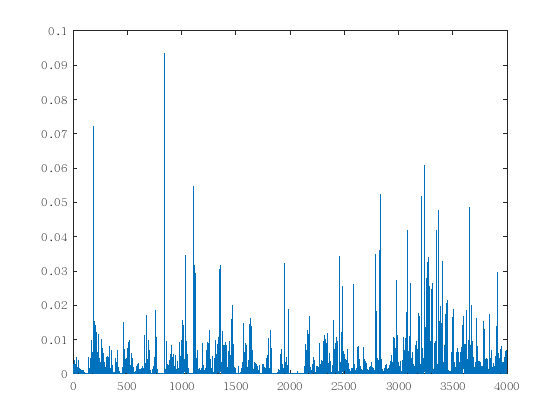

 
    ARIMA(4,0,4) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant     0.0054934      0.0036449         1.5072        0.13177
    AR{1}          0.17354        0.90424        0.19192        0.84781
    AR{2}           1.4139        0.81428         1.7364       0.082499
    AR{3}         -0.13089          0.727       -0.18005        0.85712
    AR{4}         -0.46842        0.64195       -0.72969        0.46558
    MA{1}          0.72412        0.90357        0.80141         0.4229
    MA{2}         -0.70471        0.10653        -6.6148     3.7194e-11
    MA{3}         -0.49844         0.6755       -0.73789        0.46058
    MA{4}       -0.0067408       0.015695       -0.42948        0.66757
    Variance     0.0037961     5.1112e-05         74.271              0



h = logical
   1


pValue = 0

stat = 240.6386

cValue = 3.8415

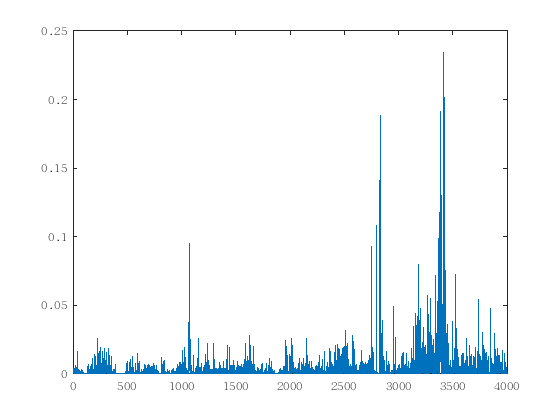

 
    ARIMA(4,0,4) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic     PValue 
                _________    _____________    __________    ________

    Constant    0.0060616      0.0037043        1.6364       0.10177
    AR{1}         0.68393        0.59719        1.1452       0.25211
    AR{2}         0.73173        0.44343        1.6502      0.098907
    AR{3}         -0.4892        0.43151       -1.1337       0.25692
    AR{4}        0.062675         0.2716       0.23076        0.8175
    MA{1}          0.3965        0.59934       0.66155       0.50826
    MA{2}        -0.25611        0.21816       -1.1739       0.24042
    MA{3}          0.1968        0.17293        1.1381        0.2551
    MA{4}        0.020425       0.075361       0.27103       0.78637
    Variance    0.0011254     1.3869e-05        81.144             0



h = logical
   1


pValue = 0

stat = 413.1345

cValue = 3.8415

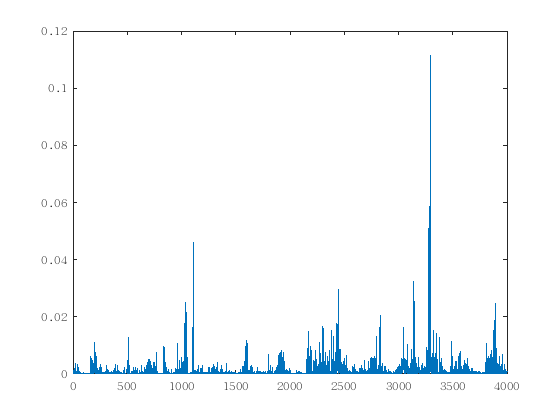

 
    ARIMA(4,0,4) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    0.00036685      0.0002045        1.7939        0.072825
    AR{1}           1.9899        0.13227        15.044      3.7797e-51
    AR{2}         -0.54096        0.28553       -1.8946        0.058148
    AR{3}               -1        0.24349       -4.1069      4.0101e-05
    AR{4}             0.55       0.086728        6.3417      2.2731e-10
    MA{1}         -0.81944        0.13373       -6.1275      8.9286e-10
    MA{2}         -0.57513        0.14769       -3.8942      9.8533e-05
    MA{3}          0.53063       0.062229        8.5271      1.5003e-17
    MA{4}         0.026266       0.022588        1.1628          0.2449
    Variance     0.0007387     7.9677e-06        92.712               0



h = logical
   1


pValue = 1.5163e-12

stat = 50.0271

cValue = 3.8415

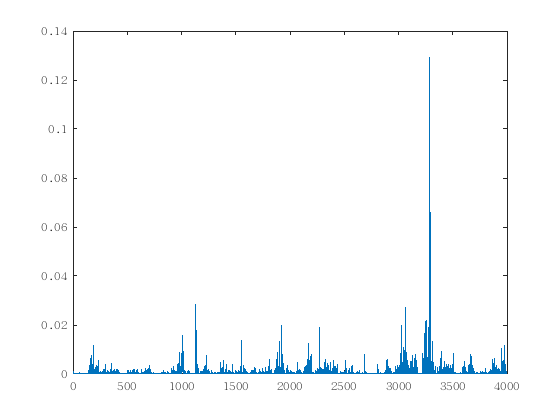

 
    ARIMA(4,0,4) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue   
                __________    _____________    __________    ___________

    Constant    0.00033695     0.00011522        2.9244        0.0034512
    AR{1}          0.28595       0.041628        6.8691       6.4593e-12
    AR{2}           1.4611       0.051544        28.346      9.2631e-177
    AR{3}          0.15845       0.044437        3.5656       0.00036296
    AR{4}          -0.9065       0.038715       -23.415      3.0391e-121
    MA{1}          0.73973       0.042535        17.391       9.6562e-68
    MA{2}         -0.72059       0.021431       -33.624      7.4938e-248
    MA{3}         -0.93013        0.03865       -24.066      5.7123e-128
    MA{4}        -0.018434        0.01019       -1.8091          0.07043
    Variance     0.0010179     1.2388e-05        82.165                0



h = logical
   1


pValue = 0

stat = 446.2474

cValue = 3.8415

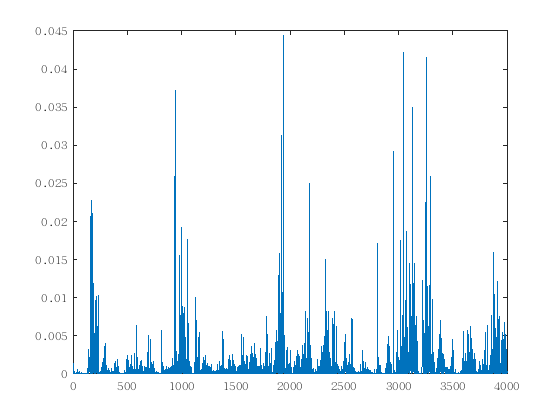

 
    ARIMA(4,0,4) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0003112     0.00013547        2.2972        0.021609
    AR{1}          1.8903        0.21312        8.8699       7.319e-19
    AR{2}         -1.2443        0.40709       -3.0566       0.0022385
    AR{3}         0.77217        0.39174        1.9711        0.048711
    AR{4}        -0.41897        0.19941       -2.1011        0.035636
    MA{1}        -0.80779        0.21199       -3.8105      0.00013869
    MA{2}          0.2943        0.22923        1.2839         0.19919
    MA{3}        -0.44048        0.18467       -2.3852         0.01707
    MA{4}       0.0077285       0.024372       0.31711         0.75116
    Variance     0.001447     1.4084e-05        102.74               0



h = logical
   1


pValue = 4.2821e-13

stat = 52.5095

cValue = 3.8415

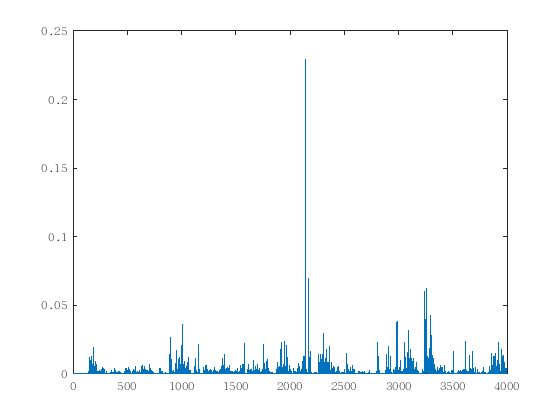

%% Test if the data possess ARCH effect
for i = 1:N
    Mdl = arima(4,0,4);
    EstMdl = estimate(Mdl,X(i,1:4000)');
    [res,~,logL] = infer(EstMdl,X(i,1:4000)');
    [h,pValue,stat,cValue] = archtest(res)
    figure
    plot(res.*res)
end

%%%%%%%%% Using the Laplacian matrix with distance
%Ldis_name = 'L_distance'
%L_dis = load(fullfile(path_data,strcat(Ldis_name,'.mat'))).name(:,:)
%%%%%%%%% Using the Laplacian matrix with corr
%Ldis_name = 'L_corr'
%L_corr = load(fullfile(path_data,strcat(Ldis_name,'.mat'))).name(:,:)
%% Get the graph from node information
param = struct

param = 不包含字段的 struct 。


param.k = 3

param = 包含以下字段的 struct :
    k: 3


G = gsp_nn_graph(Xin_node,param)

G = 包含以下字段的 struct :
             N: 6
             W: [6×6 double]
        coords: [6×2 double]
       Wkernel: @(x)create_kernel(Xin,x,kdist,Wmat)
          type: 'nearest neighbors'
         sigma: 47.8481
             A: [6×6 logical]
      directed: 0
    hypergraph: 0
      lap_type: 'combinatorial'
             L: [6×6 double]
             d: [6×1 double]
            Ne: 11
      plotting: [1×1 struct]


G = gsp_adj2vec(gsp_compute_fourier_basis(G));

G = gsp_compute_fourier_basis(G);

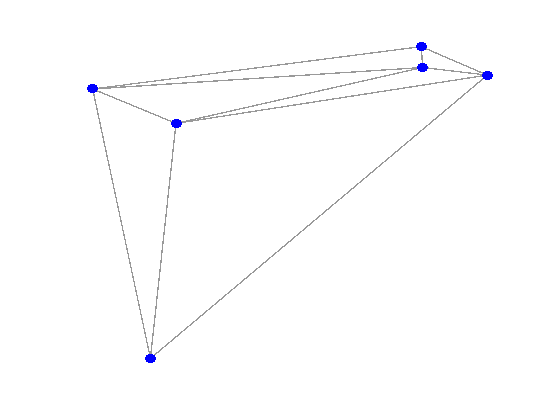

gsp_plot_graph(G)
view([0,90])


W_g = double(full(G.W))

W_g =          0    0.0000    0.7067    0.1776    0.1179         0
    0.0000         0    0.0000         0         0    0.0000
    0.7067    0.0000         0         0    0.2366    0.1809
    0.1776         0         0         0    0.9084    0.7920
    0.1179         0    0.2366    0.9084         0    0.9376
         0    0.0000    0.1809    0.7920    0.9376         0


L_g = double(full(G.L))

L_g =     1.0021   -0.0000   -0.7067   -0.1776   -0.1179         0
   -0.0000    0.0000   -0.0000         0         0   -0.0000
   -0.7067   -0.0000    1.1243         0   -0.2366   -0.1809
   -0.1776         0         0    1.8780   -0.9084   -0.7920
   -0.1179         0   -0.2366   -0.9084    2.2005   -0.9376
         0   -0.0000   -0.1809   -0.7920   -0.9376    1.9106


## preprocess

[V,D]=eig(L_g);
V_t = transpose(V);
Xhat = V_t * X

Xhat =     0.9537    0.9174    0.8658    0.8494    0.7985    0.7916    0.7479    0.7298    0.7280    0.7141    0.7029    0.6910    0.6950    0.7014    0.6821    0.6727    0.6618    0.6449    0.6142    0.5771    0.5721    0.6183    0.6443    0.6782    0.6402    0.6270    0.6152    0.5647    0.5435    0.5327    0.5211    0.5349    0.5462    0.5408    0.5406    0.5520    0.5446    0.5712    0.5923    0.5749    0.5752    0.5143    0.5101    0.5265    0.4786    0.4527    0.4416    0.4220    0.3825    0.3830
    0.1344    0.1613    0.0997    0.0858    0.0239    0.0799    0.0677    0.1288    0.1613    0.1675    0.2043    0.2202    0.2290    0.2684    0.2453    0.3236    0.3285    0.3572    0.3286    0.2923    0.3474    0.3691    0.4316    0.4058    0.3382    0.3441    0.3599    0.3613    0.3814    0.3650    0.3385    0.2900    0.2426    0.1815    0.1181    0.1130    0.0528    0.0515    0.0844    0.0498    0.0285   -0.0712   -0.0693   -0.0767   -0.0976   -0.1283   -0.1234   -0.1570   -0.1711  

%%%%% 
T=400
X_5 = zeros(N,T)
Xhat_5 = zeros(N,T)

for i = 1:T
    X_5(:,i) = X(:,(i-1)*50+1);
    Xhat_5(:,i) = Xhat(:,(i-1)*50+1);
end

%%%%%%%% test the res uncorrelated 
res_whole1 = zeros(N,T)
for i = 1:N
    Mdl = arima('ARLags',[1,2,3,4],'MALags',[1,2,3,4],'Variance',garch(1,1));
    EstMdl = estimate(Mdl,Xhat_5(i,1:T)');
    [res_whole1(i,:),~,logL] = infer(EstMdl,Xhat_5(i,1:T)');

end
C1 = cov(res_whole1')
R1 = corrcoef(res_whole1')
imagesc(R1);
colorbar

%%%%%%%% test the original res correlated 
res_whole = zeros(N,T)
for i = 1:N
    Mdl = arima('ARLags',[1,2,3,4],'MALags',[1,2,3,4],'Variance',garch(1,1));
    EstMdl = estimate(Mdl,X_5(i,1:T)');
    [res_whole(i,:),~,logL] = infer(EstMdl,X_5(i,1:T)');

end


C = cov(res_whole')
R = corrcoef(res_whole') 
imagesc(R);
colorbar

%%% statistical value for GARCH in frequency, ARCH does exist
H_f = zeros(N,1)
PVALUE_f = zeros(N,1)
STAT_f = zeros(N,1)
CVALUE_f = zeros(N,1)
for i = 1:N
    Mdl = arima(4,0,4);
    EstMdl = estimate(Mdl,Xhat(i,:)');
    [res,~,logL] = infer(EstMdl,Xhat(i,:)');
    [H_f(i,1),PVALUE_f(i,1),STAT_f(i,1),CVALUE_f(i,1)] = archtest(res)
    %figure
    %plot(res.*res)
end


%%% statistical value for GARCH in original, ARCH does exist
H_o = zeros(N,1)
PVALUE_o = zeros(N,1)
STAT_o = zeros(N,1)
CVALUE_o = zeros(N,1)
for i = 1:N
    Mdl = arima(4,0,4);
    EstMdl = estimate(Mdl,X(i,:)');
    [res,~,logL] = infer(EstMdl,X(i,:)');
    [H_o(i,1),PVALUE_o(i,1),STAT_o(i,1),CVALUE_o(i,1)] = archtest(res)
    %figure
    %plot(res.*res)
end

%%%% test on MAE,RNMSE,MAPE for frequency domain
AR_Order = 5;
MA_Order = 5;
length = T;
sample_rate = 0.8;
p_val = 0.875;
index_in = ceil(length* sample_rate);
index_train = ceil(index_in * p_val);
val_L = index_in-index_train;
error_record = zeros(AR_Order*(MA_Order+1),N,3);
record_sum   = zeros(AR_Order *(MA_Order+1),3);
iter = 0;
small_matrix = ones(1,val_L);

for AR = 1:AR_Order
    for MA = 0:MA_Order
        pre_val = zeros(N,val_L);
        error_val   = zeros(N,val_L);
        for i = 1:N
            X_train = Xhat(i,1:index_train)';
            Mdl = arima(AR,0,MA);
            EstMdl = estimate(Mdl,X_train);
            for index=1:val_L
                pre_val(i,index) = forecast(EstMdl,1,'Y0',Xhat(i,1:index_train-1+index)');
            end
            iter = iter + 1
    end
    
    pos_temp = (AR-1)*(MA_Order+1) + MA+1
    Pre_true = V * pre_val;
    error_val = abs(Pre_true - X(:,index_train+1:index_in));
    error_record(pos_temp,:,1) = sum(error_val,2)/val_L;
    error_record(pos_temp,:,2) = sum(error_val./(X(:,index_train+1:index_in) + small_matrix),2)/(val_L);
    error_record(pos_temp,:,3) = sqrt(sum(error_val.^2,2)./sum(X(:,index_train+1:index_in).^2,2));
    record_sum(pos_temp,1) = sum(error_record(pos_temp,:,1))/N;
    record_sum(pos_temp,2) = sum(error_record(pos_temp,:,2))/N;
    record_sum(pos_temp,3) = sqrt(sum(sum(error_val.^2,2))/sum(sum(X(:,index_train+1:index_in).^2,2)));

    end
end

[m,index_f]= min(record_sum(:,3))
AR_f = fix(index_f / 6) + 1
MA_f = index_f - (AR_f-1)*6 - 1

%%%% test on MAE,RNMSE,MAPE for original domain
AR_Order = 5;
MA_Order = 5;
length = T;
sample_rate = 0.8;
p_val = 0.875;
index_in = ceil(length* sample_rate);
index_train = ceil(index_in * p_val);
val_L = index_in-index_train;
error_record = zeros(AR_Order*(MA_Order+1),N,3);
record_sum1   = zeros(AR_Order *(MA_Order+1),3);
iter = 0;
small_matrix = ones(1,val_L);

for AR = 1:AR_Order
    for MA = 0:MA_Order
        pre_val = zeros(N,val_L);
        error_val   = zeros(N,val_L);
        for i = 1:N
            X_train = X(i,1:index_train)';
            Mdl = arima(AR,0,MA);
            EstMdl = estimate(Mdl,X_train);
            for index=1:val_L
                pre_val(i,index) = forecast(EstMdl,1,'Y0',X(i,1:index_train-1+index)');
            end
            iter = iter + 1
    end
    
    pos_temp = (AR-1)*(MA_Order+1) + MA+1
    Pre_true = pre_val;
    error_val = abs(Pre_true - X(:,index_train+1:index_in));
    error_record(pos_temp,:,1) = sum(error_val,2)/val_L;
    error_record(pos_temp,:,2) = sum(error_val./(X(:,index_train+1:index_in) + small_matrix),2)/(val_L);
    error_record(pos_temp,:,3) = sqrt(sum(error_val.^2,2)./sum(X(:,index_train+1:index_in).^2,2));
    record_sum1(pos_temp,1) = sum(error_record(pos_temp,:,1))/N;
    record_sum1(pos_temp,2) = sum(error_record(pos_temp,:,2))/N;
    record_sum1(pos_temp,3) = sqrt(sum(sum(error_val.^2,2))/sum(sum(X(:,index_train+1:index_in).^2,2)));

    end
end

[m,index_o]= min(record_sum1(:,3))
AR_o = index_o / 6
MA_o = index_o - (AR_o-1)*6 - 1

%%%BEST ARMA(4,4) val test p, q, 
P_Order = 1;
Q_Order = 1;
length = T;
sample_rate = 0.8;
p_val = 0.875;
index_in = ceil(length* sample_rate);
index_train = ceil(index_in * p_val);
val_L = index_in-index_train;
error_record = zeros((P_Order+1)*Q_Order,N,3);
record_sum2   = zeros((P_Order+1)*Q_Order,3);
iter = 0;
small_matrix = ones(N,val_L);

for p = 0:P_Order
    for q = 1:Q_Order
        pre_val = zeros(N,val_L);
        error_val   = zeros(N,val_L);
        for i = 1:N
            X_train = Xhat(i,1:index_train)';
            Mdl = arima('ARLags',[1,2,3,4],'MALags',[1,2,3,4],'Variance',garch(p,q));
            %opts = optimset('fmincon');
            %opts.Algorithm = 'interior-point';
            %EstMdl = estimate(Mdl,X_train,'options',opts);
            EstMdl = estimate(Mdl,X_train);
            for index=1:val_L
                pre_val(i,index) = forecast(EstMdl,1,'Y0',Xhat(i,1:index_train-1+index)');
            end
            iter = iter + 1
    end
    
    
    Pre_true = V * pre_val;
    error_val = abs(Pre_true - X(:,index_train+1:index_in));
    error_record((p)*3 + q,:,1) = sum(error_val,2)/val_L;
    error_record((p)*3 + q,:,2) = sum(error_val./(X(:,index_train+1:index_in)+small_matrix),2)/(val_L);
    error_record((p)*3 + q,:,3) = sqrt(sum(error_val.^2,2)./sum(X(:,index_train+1:index_in).^2,2));
    record_sum2((p)*3 + q,1) = sum(error_record((p)*3 + q,:,1))/N;
    record_sum2((p)*3 + q,2) = sum(error_record((p)*3 + q,:,2))/N;
    record_sum2((p)*3 + q,3) = sqrt(sum(sum(error_val.^2,2))/sum(sum(X(:,index_train+1:index_in).^2,2)));

    end
end

%%%BEST ARMA(4,4) val test p, q, 
P_Order = 1;
Q_Order = 1;
length = T;
sample_rate = 0.8;
p_val = 0.875;
index_in = ceil(length* sample_rate);
index_train = ceil(index_in * p_val);
val_L = index_in-index_train;
error_record = zeros((P_Order+1)*Q_Order,N,3);
record_sum3   = zeros((P_Order+1)*Q_Order,3);
iter = 0;
small_matrix = ones(N,val_L);

for p = 0:P_Order
    for q = 1:Q_Order
        pre_val = zeros(N,val_L);
        error_val   = zeros(N,val_L);
        for i = 1:N
            X_train = X(i,1:index_train)';
            Mdl = arima('ARLags',[1,2],'MALags',[1,2,3,4,5],'Variance',garch(p,q));
            %opts = optimset('fmincon');
            %opts.Algorithm = 'interior-point';
            %EstMdl = estimate(Mdl,X_train,'options',opts);
            EstMdl = estimate(Mdl,X_train);
            for index=1:val_L
                pre_val(i,index) = forecast(EstMdl,1,'Y0',X(i,1:index_train-1+index)');
            end
            iter = iter + 1
    end
    
    Pre_true = pre_val;
    error_val = abs(Pre_true - X(:,index_train+1:index_in));
    error_record((p) + q,:,1) = sum(error_val,2)/val_L;
    error_record((p) + q,:,2) = sum(error_val./(X(:,index_train+1:index_in)+small_matrix),2)/(val_L);
    error_record((p) + q,:,3) = sqrt(sum(error_val.^2,2)./sum(X(:,index_train+1:index_in).^2,2));
    record_sum3((p) + q,1) = sum(error_record((p) + q,:,1))/N;
    record_sum3((p) + q,2) = sum(error_record((p) + q,:,2))/N;
    record_sum3((p) + q,3) = sqrt(sum(sum(error_val.^2,2))/sum(sum(X(:,index_train+1:index_in).^2,2)));

    end
end

AR_f = 4

AR_f = 4

MA_f = 4

MA_f = 4

AR_o = 2

AR_o = 2

MA_o = 5

MA_o = 5

%%% optimial parameter is ARMA(4,4)-garch(1,1)
AR_Order = AR_f

AR_Order = 4

MA_Order = MA_f

MA_Order = 4

length = T

length = 20000

sample_rate = 0.8

sample_rate = 0.8000

p_val = 0.875

p_val = 0.8750

index_in = ceil(length* sample_rate)

index_in = 16000

index_train = ceil(index_in * p_val)

index_train = 14000

test_L = length  - index_in

test_L = 4000

H = 40

H = 40

prediction = zeros(N,test_L,H)

prediction = prediction(:,:,1) =

  列 1 至 1,666

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

var_f_ggarch = zeros(N,test_L,H)

var_f_ggarch = var_f_ggarch(:,:,1) =

  列 1 至 1,666

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

iter = 0

iter = 0


for i = 1:1:N
    X_train = Xhat(i,1:index_train)';
    X_val = Xhat(i,index_train+1:index_in)';
    X_test = Xhat(i,index_in+1:end)';
            
    %Mdl = arima(AR_Order,0,0);
    Mdl = arima('ARLags',[1,2,3,4],'MALags',[1,2,3,4],'Variance',garch(1,1));
    EstMdl = estimate(Mdl,X_train);
    [res,~,logL] = infer(EstMdl,X_train);
    
    for index = 1:1:T - index_in
        for j = 1:1:H
            if j == 1
                [prediction(i,index,j),var_f_ggarch(i,index,j)] =forecast(EstMdl,j,'Y0',Xhat(i,1:index_in -j +index)');
            else
                [temp,v_temp] = forecast(EstMdl,j,'Y0',Xhat(i,1:index_in -j +index)');
                var_f_ggarch(i,index,j)=v_temp(j,1);
                prediction(i,index,j) = temp(j,1);
            end
        end
    end
    iter = iter + 1
end

 
    ARIMA(4,0,4) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    0.00051528     0.00014971        3.4418      0.00057781
    AR{1}           1.3495        0.18601        7.2549      4.0192e-13
    AR{2}          0.44578        0.30738        1.4503         0.14698
    AR{3}               -1        0.29845       -3.3506      0.00080636
    AR{4}          0.20407        0.17152        1.1898         0.23411
    MA{1}          -0.3199        0.18572       -1.7225        0.084985
    MA{2}         -0.69505        0.16984       -4.0923      4.2718e-05
    MA{3}          0.22275        0.16144        1.3797         0.16767
    MA{4}        -0.057151       0.011806       -4.8409      1.2927e-06

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue   
        

iter = 1

 
    ARIMA(4,0,4) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    0.00089643     0.00057308         1.5642        0.11776
    AR{1}          0.42765        0.46304        0.92357        0.35571
    AR{2}           1.1695        0.33008         3.5431     0.00039545
    AR{3}         -0.31251         0.4113       -0.75981        0.44737
    AR{4}         -0.29527        0.27175        -1.0865        0.27725
    MA{1}          0.41898        0.46298        0.90495        0.36549
    MA{2}         -0.64621        0.14047        -4.6003     4.2179e-06
    MA{3}         -0.17112        0.27233       -0.62834        0.52978
    MA{4}         0.035186       0.058227        0.60429        0.54565

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue   
        

iter = 2

 
    ARIMA(4,0,4) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic     PValue 
                __________    _____________    __________    ________

    Constant    0.00043881     0.00023224         1.8895     0.058828
    AR{1}          0.92355        0.50756         1.8196     0.068824
    AR{2}          0.20461        0.87324        0.23431      0.81474
    AR{3}          0.24212        0.63235        0.38289       0.7018
    AR{4}         -0.38164         0.2658        -1.4358      0.15106
    MA{1}          0.15796        0.50815        0.31086      0.75591
    MA{2}        -0.010232        0.41544       -0.02463      0.98035
    MA{3}         -0.27275        0.23558        -1.1578      0.24695
    MA{4}         0.040273       0.023427         1.7191     0.085597

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue   
                __________    

iter = 3

 
    ARIMA(4,0,4) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    0.00040475      0.0001939        2.0874        0.036855
    AR{1}          0.61784        0.13598        4.5437      5.5283e-06
    AR{2}          0.31912        0.13974        2.2837        0.022388
    AR{3}          0.54782        0.12718        4.3075      1.6508e-05
    AR{4}         -0.50326       0.074713        -6.736      1.6281e-11
    MA{1}          0.39285        0.13611        2.8862       0.0038993
    MA{2}          0.12185       0.086643        1.4064         0.15961
    MA{3}         -0.41373       0.076503        -5.408      6.3738e-08
    MA{4}         0.034005       0.014927         2.278        0.022726

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
             

iter = 4

 
    ARIMA(4,0,4) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    0.00016986     0.00021713         0.7823        0.43404
    AR{1}         0.079484         0.2547        0.31207        0.75499
    AR{2}          0.81007        0.26178         3.0944      0.0019719
    AR{3}          0.28182        0.25097         1.1229        0.26147
    AR{4}         -0.22258        0.19022        -1.1701        0.24194
    MA{1}          0.94311        0.25481         3.7013     0.00021453
    MA{2}          0.14081        0.23046        0.61101        0.54119
    MA{3}         -0.16534        0.19424       -0.85123        0.39464
    MA{4}         0.026439       0.011362         2.3269       0.019972

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
         

iter = 5

 
    ARIMA(4,0,4) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0011562     0.00032248         3.5852     0.00033687
    AR{1}         0.21327        0.22264        0.95792         0.3381
    AR{2}         0.09924         0.2286        0.43413         0.6642
    AR{3}       -0.025085        0.17594       -0.14257        0.88663
    AR{4}         0.61853        0.15905         3.8888     0.00010072
    MA{1}         0.68625        0.22334         3.0727      0.0021211
    MA{2}         0.57257        0.20121         2.8456      0.0044323
    MA{3}         0.60521        0.15473         3.9114     9.1751e-05
    MA{4}       -0.036932       0.015896        -2.3234       0.020157

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                ____

iter = 6


prediction1 = zeros(N,test_L,H)

prediction1 = prediction1(:,:,1) =

  列 1 至 1,666

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 


iter = 0

iter = 0


for i = 1:1:N
    X_train = Xhat(i,1:index_train)';
    X_val = Xhat(i,index_train+1:index_in)';
    X_test = Xhat(i,index_in+1:end)';
            
    Mdl = arima(AR_Order,0,MA_Order);
    EstMdl = estimate(Mdl,X_train);
    [res,~,logL] = infer(EstMdl,X_train);
    
    for index = 1:1:T - index_in
        for j = 1:1:H
            if j == 1
                prediction1(i,index,j) =forecast(EstMdl,j,'Y0',Xhat(i,1:index_in -j +index)');
            else
                temp = forecast(EstMdl,j,'Y0',Xhat(i,1:index_in -j +index)');
                prediction1(i,index,j) = temp(j,1);
            end
        end
    end
    iter = iter + 1
end

 
    ARIMA(4,0,4) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic     PValue 
                _________    _____________    __________    ________

    Constant    0.0012115      0.0010666         1.1358      0.25604
    AR{1}           1.818        0.98385         1.8478     0.064633
    AR{2}         -1.2698         1.9442       -0.65311      0.51368
    AR{3}         0.99738         1.8688        0.53371      0.59354
    AR{4}        -0.54684        0.89458       -0.61128      0.54101
    MA{1}        -0.78194        0.98378       -0.79483      0.42671
    MA{2}         0.47435         1.1498        0.41256      0.67993
    MA{3}         -0.5265        0.85451       -0.61614       0.5378
    MA{4}        0.013926       0.015548        0.89569      0.37042
    Variance    0.0018304     1.3347e-05         137.14            0



iter = 1

 
    ARIMA(4,0,4) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0046035      0.0013912          3.309      0.0009364
    AR{1}        -0.51026        0.20029        -2.5477       0.010845
    AR{2}          0.9541       0.059914         15.925     4.2832e-57
    AR{3}         0.49026         0.1965         2.4949       0.012599
    AR{4}        0.020299        0.06009        0.33781         0.7355
    MA{1}          1.3748         0.2005         6.8567     7.0472e-12
    MA{2}         0.34843         0.1552         2.2451       0.024763
    MA{3}       -0.041928       0.066691       -0.62869        0.52955
    MA{4}       -0.013797       0.012172        -1.1335          0.257
    Variance    0.0027296     1.9297e-05         141.45              0



iter = 2

 
    ARIMA(4,0,4) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0025861     0.00050995        5.0712      3.9533e-07
    AR{1}         0.31882       0.040004        7.9698      1.5887e-15
    AR{2}         0.76513       0.043001        17.793      7.9654e-71
    AR{3}         0.53469       0.041345        12.932      2.9564e-38
    AR{4}        -0.64285       0.030776       -20.888      6.8612e-97
    MA{1}         0.74278       0.040211        18.472      3.4739e-76
    MA{2}        0.043062       0.037367        1.1524         0.24916
    MA{3}        -0.48782        0.03385       -14.411      4.3873e-47
    MA{4}        0.061089      0.0077165        7.9168      2.4377e-15
    Variance    0.0015467     9.9882e-06        154.86               0



iter = 3

 
    ARIMA(4,0,4) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0065098      0.0012433        5.2358      1.6428e-07
    AR{1}        -0.26093       0.084986       -3.0703       0.0021388
    AR{2}         0.64253       0.083133         7.729       1.084e-14
    AR{3}         0.46445       0.084489        5.4971      3.8603e-08
    AR{4}        0.074921       0.082073       0.91286         0.36132
    MA{1}          1.2433       0.084763        14.668      1.0283e-48
    MA{2}         0.62122          0.111        5.5967      2.1845e-08
    MA{3}         0.18518       0.082818        2.2359        0.025355
    MA{4}        0.070833      0.0065243        10.857      1.8507e-27
    Variance    0.0014843     9.3008e-06        159.59               0



iter = 4

 
    ARIMA(4,0,4) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue   
                __________    _____________    __________    ___________

    Constant    0.00049708     0.00058019       0.85676          0.39158
    AR{1}           1.0207       0.042625        23.946      1.0183e-126
    AR{2}         -0.14457       0.066989       -2.1582         0.030912
    AR{3}         -0.78193       0.064533       -12.117       8.6059e-34
    AR{4}          0.82059       0.037366        21.961      6.8557e-107
    MA{1}        -0.060831        0.04284         -1.42          0.15562
    MA{2}         0.075854       0.037878        2.0026         0.045221
    MA{3}          0.87358       0.038051        22.958      1.2203e-116
    MA{4}        -0.011423        0.00527       -2.1675         0.030199
    Variance     0.0012315     6.1724e-06        199.52                0



iter = 5

 
    ARIMA(4,0,4) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue   
                _________    _____________    __________    ___________

    Constant    9.175e-05     9.3134e-05       0.98514          0.32455
    AR{1}          1.3569       0.056379        24.068      5.4721e-128
    AR{2}        -0.84625       0.098702       -8.5738       1.0012e-17
    AR{3}               1       0.080897        12.361        4.224e-35
    AR{4}         -0.5222        0.03924       -13.308       2.0824e-40
    MA{1}         -0.5451       0.056633        -9.625        6.271e-22
    MA{2}         0.44762       0.066749        6.7061       1.9993e-11
    MA{3}        -0.60741       0.047476       -12.794       1.7673e-37
    MA{4}        0.014153      0.0095886         1.476          0.13995
    Variance    0.0011908     6.0449e-06        196.99                0



iter = 6


prediction2 = zeros(N,test_L,H)

prediction2 = prediction2(:,:,1) =

  列 1 至 1,666

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

var_garch = zeros(N,test_L,H)

var_garch = var_garch(:,:,1) =

  列 1 至 1,666

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

iter = 0

iter = 0


for i = 1:1:N
    X_train = X(i,1:index_train)';
    X_val = X(i,index_train+1:index_in)';
    X_test = X(i,index_in+1:end)';
            
    %Mdl = arima(AR_Order,0,0);
    Mdl = arima('ARLags',[1,2],'MALags',[1,2,3,4,5],'Variance',garch(1,1));
    EstMdl = estimate(Mdl,X_train);
    [res,~,logL] = infer(EstMdl,X_train);
    
    for index = 1:1:T - index_in
        for j = 1:1:H
            if j == 1
                [prediction2(i,index,j),var_garch(i,index,j)] =forecast(EstMdl,j,'Y0',X(i,1:index_in -j +index)');
            else
                [temp,v_temp] = forecast(EstMdl,j,'Y0',X(i,1:index_in -j +index)');
                var_garch(i,index,j)=v_temp(j,1);
                prediction2(i,index,j) = temp(j,1);
            end
        end
    end
    iter = iter + 1
end

 
    ARIMA(2,0,5) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic      PValue  
                ___________    _____________    __________    __________

    Constant     0.00012158     4.1018e-05          2.964      0.0030369
    AR{1}            1.9035        0.01599         119.05              0
    AR{2}          -0.90433       0.015887        -56.924              0
    MA{1}           -0.8591       0.017808        -48.243              0
    MA{2}          0.051372       0.010716         4.7941     1.6338e-06
    MA{3}          -0.02241      0.0099123        -2.2608       0.023772
    MA{4}         -0.025438      0.0089365        -2.8466       0.004419
    MA{5}       -0.00065682      0.0076724      -0.085608        0.93178

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Co

iter = 1

 
    ARIMA(2,0,5) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic     PValue  
                _________    _____________    __________    _________

    Constant    0.0034143      0.0011891        2.8714      0.0040862
    AR{1}         0.46157        0.29347        1.5728        0.11577
    AR{2}         0.52894        0.29172        1.8132         0.0698
    MA{1}         0.33477        0.29363        1.1401        0.25425
    MA{2}       -0.080998       0.058563       -1.3831        0.16664
    MA{3}        0.012963       0.012105        1.0708        0.28424
    MA{4}        0.015132       0.010043        1.5067        0.13188
    MA{5}        0.028809      0.0093309        3.0875      0.0020184

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    7.3728e-05     1.013

iter = 2

 
    ARIMA(2,0,5) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    9.4252e-05     4.5147e-05        2.0876        0.036831
    AR{1}           1.8645        0.01569        118.83               0
    AR{2}         -0.86528       0.015629       -55.365               0
    MA{1}         -0.83175        0.01706       -48.754               0
    MA{2}          0.10922      0.0094711        11.532      9.1119e-31
    MA{3}        0.0065839      0.0094505       0.69667         0.48601
    MA{4}        -0.027908      0.0088569        -3.151       0.0016272
    MA{5}        0.0040234      0.0082408       0.48823         0.62538

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue   
                __________    _____________    __________    ___________

    Co

iter = 3

 
    ARIMA(2,0,5) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    3.6078e-05     1.7732e-05        2.0346         0.04189
    AR{1}           1.8965       0.017327        109.46               0
    AR{2}         -0.89707       0.017263       -51.964               0
    MA{1}         -0.72855       0.018917       -38.513               0
    MA{2}         -0.02971      0.0084629       -3.5106      0.00044711
    MA{3}        0.0059576      0.0090804        0.6561         0.51176
    MA{4}         -0.03111      0.0095327       -3.2636       0.0011003
    MA{5}         -0.01746      0.0078724       -2.2179        0.026558

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue   
                __________    _____________    __________    ___________

    Co

iter = 4

 
    ARIMA(2,0,5) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0002118     0.00014425        1.4682         0.14204
    AR{1}          1.5288        0.11055        13.829      1.7136e-43
    AR{2}         -0.5323        0.10978       -4.8489      1.2412e-06
    MA{1}        -0.46514        0.11231       -4.1417      3.4473e-05
    MA{2}         0.04949       0.012096        4.0914       4.287e-05
    MA{3}        0.031723       0.013154        2.4116        0.015882
    MA{4}       0.0043701       0.012159       0.35942         0.71928
    MA{5}        0.018408       0.011631        1.5827         0.11349

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant    1.3553e-05

iter = 5

 
    ARIMA(2,0,5) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue   
                __________    _____________    __________    ___________

    Constant     4.179e-05     2.2968e-05         1.8195        0.068832
    AR{1}            1.905       0.022322         85.339               0
    AR{2}         -0.90551       0.022231        -40.732               0
    MA{1}         -0.86508       0.023161        -37.351     2.4745e-305
    MA{2}        0.0075371        0.01019        0.73966         0.45951
    MA{3}         0.015854       0.010199         1.5544         0.12008
    MA{4}       -0.0055045      0.0092271       -0.59656          0.5508
    MA{5}        -0.019582      0.0070601        -2.7736       0.0055437

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Co

iter = 6


prediction3 = zeros(N,test_L,H)

prediction3 = prediction3(:,:,1) =

  列 1 至 1,666

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 


iter = 0

iter = 0


for i = 1:1:N
    X_train = X(i,1:index_train)';
    X_val = X(i,index_train+1:index_in)';
    X_test = X(i,index_in+1:end)';
            
    Mdl = arima(AR_o,0,MA_o);
    EstMdl = estimate(Mdl,X_train);
    [res,~,logL] = infer(EstMdl,X_train);
    
    for index = 1:1:T - index_in
        for j = 1:1:H
            if j == 1
                prediction3(i,index,j) =forecast(EstMdl,j,'Y0',X(i,1:index_in -j +index)');
            else
                temp = forecast(EstMdl,j,'Y0',X(i,1:index_in -j +index)');
                prediction3(i,index,j) = temp(j,1);
            end
        end
    end
    iter = iter + 1
end

 
    ARIMA(2,0,5) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    0.00070589     0.00038092         1.8531       0.063864
    AR{1}           1.8943         0.0508         37.288     2.526e-304
    AR{2}         -0.89615       0.049825        -17.986     2.5196e-72
    MA{1}         -0.86478       0.051056        -16.938     2.3628e-64
    MA{2}         0.014318      0.0077056         1.8581        0.06315
    MA{3}       0.00077575      0.0083144       0.093302        0.92566
    MA{4}        -0.032961      0.0086096        -3.8284     0.00012897
    MA{5}        -0.003681      0.0067462       -0.54564        0.58531
    Variance     0.0019569     1.2402e-05         157.79              0



iter = 1

 
    ARIMA(2,0,5) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant      0.012198      0.0019726        6.1838      6.2591e-10
    AR{1}       -0.0043023      0.0040706       -1.0569         0.29055
    AR{2}          0.97856      0.0040846        239.58               0
    MA{1}          0.84596      0.0064145        131.88               0
    MA{2}         -0.14989      0.0073757       -20.322      8.1414e-92
    MA{3}        -0.027861       0.007879       -3.5361      0.00040604
    MA{4}        -0.022625      0.0075582       -2.9934       0.0027587
    MA{5}        0.0030539      0.0065317       0.46756          0.6401
    Variance     0.0029564     2.0301e-05        145.63               0



iter = 2

 
    ARIMA(2,0,5) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0072314      0.0019805        3.6514      0.00026084
    AR{1}         0.24846        0.26098       0.95203         0.34108
    AR{2}         0.73625        0.25846        2.8486       0.0043918
    MA{1}         0.75604        0.26094        2.8973       0.0037634
    MA{2}         0.11712      0.0069191        16.928      2.8161e-64
    MA{3}         0.16457         0.0297         5.541       3.007e-08
    MA{4}         0.10799       0.023144        4.6662      3.0688e-06
    MA{5}        0.027521       0.014471        1.9018        0.057195
    Variance    0.0012102     5.2583e-06        230.15               0



iter = 3

 
    ARIMA(2,0,5) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    0.00012462     3.1922e-05         3.9039     9.4659e-05
    AR{1}           1.9761      0.0058493         337.83              0
    AR{2}         -0.97649      0.0057618        -169.48              0
    MA{1}           -0.854        0.00678        -125.96              0
    MA{2}        -0.070635      0.0052479         -13.46     2.7031e-41
    MA{3}       -0.0019097      0.0052329       -0.36494        0.71516
    MA{4}        -0.030781      0.0054626        -5.6349     1.7518e-08
    MA{5}        -0.012189      0.0044998        -2.7087      0.0067542
    Variance    0.00084835      3.676e-06         230.78              0



iter = 4

 
    ARIMA(2,0,5) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant     0.0056784       0.001517        3.7432      0.00018168
    AR{1}          0.41879        0.23376        1.7915        0.073205
    AR{2}          0.56363        0.23098        2.4402         0.01468
    MA{1}          0.53947        0.23415         2.304        0.021224
    MA{2}         0.020494      0.0087488        2.3424        0.019158
    MA{3}         0.063424       0.010822        5.8604      4.6173e-09
    MA{4}         0.038548       0.012223        3.1538       0.0016118
    MA{5}       -0.0031977      0.0075382       -0.4242         0.67142
    Variance     0.0013962      6.589e-06         211.9               0



iter = 5

 
    ARIMA(2,0,5) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant     0.0070812      0.0014979        4.7275      2.2732e-06
    AR{1}          0.17794        0.06113        2.9109        0.003604
    AR{2}          0.80092       0.060423        13.255      4.2151e-40
    MA{1}          0.80346       0.061469        13.071      4.8224e-39
    MA{2}        -0.030475       0.005664       -5.3805      7.4275e-08
    MA{3}       -0.0097928      0.0063991       -1.5303         0.12593
    MA{4}         0.027637      0.0063611        4.3447      1.3948e-05
    MA{5}         0.030483      0.0047945         6.358      2.0446e-10
    Variance     0.0017659     7.8891e-06        223.84               0



iter = 6


prediction4 = zeros(N,test_L,H)

prediction4 = prediction4(:,:,1) =

  列 1 至 1,666

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

var_f_gegarch = zeros(N,test_L,H);
iter = 0

iter = 0


for i = 1:1:N
    X_train = Xhat(i,1:index_train)';
    X_val = Xhat(i,index_train+1:index_in)';
    X_test = Xhat(i,index_in+1:end)';
            
    %Mdl = arima(AR_Order,0,0);
    Mdl = arima('ARLags',[1,2,3,4],'MALags',[1,2,3,4],'Variance',egarch(1,1));
    EstMdl = estimate(Mdl,X_train);
    [res,~,logL] = infer(EstMdl,X_train);
    
    for index = 1:1:T - index_in
        for j = 1:1:H
            if j == 1
                [prediction4(i,index,j),var_f_gegarch(i,index,j)] =forecast(EstMdl,j,'Y0',Xhat(i,1:index_in -j +index)');
            else
                [temp,v_temp] = forecast(EstMdl,j,'Y0',Xhat(i,1:index_in -j +index)');
                var_f_gegarch(i,index,j)=v_temp(j,1);
                prediction4(i,index,j) = temp(j,1);
            end
        end
    end
    iter = iter + 1
end

 
    ARIMA(4,0,4) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    0.00072509     0.00013614         5.3259     1.0045e-07
    AR{1}           1.4285       0.025931         55.087              0
    AR{2}        -0.075159        0.22861       -0.32877        0.74233
    AR{3}         -0.22477        0.42717        -0.5262        0.59875
    AR{4}         -0.12937        0.20549       -0.62959        0.52896
    MA{1}         -0.38537       0.027184        -14.177     1.2765e-45
    MA{2}         -0.27516        0.22222        -1.2382        0.21564
    MA{3}        -0.095963         0.1973       -0.48639        0.62669
    MA{4}        -0.032087       0.013552        -2.3676       0.017902

 
 
    EGARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                    Value      StandardError    TStatistic      PValue   
      

iter = 1

 
    ARIMA(4,0,4) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0016278     0.00053161          3.062      0.0021983
    AR{1}       -0.028701        0.12318       -0.23299        0.81577
    AR{2}           1.382       0.086148         16.042     6.4927e-58
    AR{3}         0.25792        0.11403         2.2617       0.023714
    AR{4}        -0.62777       0.076937        -8.1595     3.3635e-16
    MA{1}         0.87686        0.12328          7.113     1.1357e-12
    MA{2}        -0.47443        0.13161        -3.6047     0.00031249
    MA{3}        -0.51193       0.072233        -7.0872      1.369e-12
    MA{4}         0.11391       0.016197         7.0332     2.0186e-12

 
 
    EGARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                     Value      StandardError    TStatistic      PValue   
                

iter = 2

 
    ARIMA(4,0,4) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    0.00061789     0.00013989         4.4171     1.0002e-05
    AR{1}          0.91465        0.12592         7.2635     3.7722e-13
    AR{2}        -0.075949        0.21089       -0.36013        0.71875
    AR{3}          0.73351        0.16077         4.5626     5.0533e-06
    AR{4}          -0.5846       0.077924        -7.5021     6.2816e-14
    MA{1}          0.17732        0.12592         1.4082        0.15907
    MA{2}          0.28641         0.1031          2.778      0.0054691
    MA{3}         -0.44874       0.070358         -6.378     1.7946e-10
    MA{4}         0.058956       0.011123         5.3002     1.1566e-07

 
 
    EGARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                    Value      StandardError    TStatistic      PValue  
       

iter = 3

 
    ARIMA(4,0,4) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0006851     0.00012793        5.3553      8.5415e-08
    AR{1}         0.56427        0.10025        5.6287      1.8157e-08
    AR{2}          0.3535        0.11339        3.1175       0.0018237
    AR{3}         0.60741        0.11139        5.4529      4.9567e-08
    AR{4}        -0.54345       0.067927       -8.0005      1.2393e-15
    MA{1}         0.44508        0.10028        4.4386      9.0536e-06
    MA{2}         0.13624       0.082576        1.6498         0.09898
    MA{3}        -0.45994        0.07264       -6.3318      2.4239e-10
    MA{4}        0.040003        0.01183        3.3814      0.00072121

 
 
    EGARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                    Value      StandardError    TStatistic      PValue  
                  

iter = 4

 
    ARIMA(4,0,4) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic     PValue  
                __________    _____________    __________    _________

    Constant    5.5646e-05     5.5681e-05        0.99937       0.31762
    AR{1}           1.2344        0.41283         2.9902     0.0027882
    AR{2}          0.39034        0.40652         0.9602       0.33696
    AR{3}               -1        0.36125        -2.7682     0.0056373
    AR{4}          0.36147        0.16909         2.1377      0.032541
    MA{1}         -0.21559        0.41312       -0.52185       0.60177
    MA{2}         -0.61725        0.24337        -2.5362      0.011205
    MA{3}           0.3571        0.15858         2.2519      0.024329
    MA{4}       -0.0072119       0.017182       -0.41973       0.67468

 
 
    EGARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                    Value      StandardError    TStatistic      PValue   
                 

iter = 5

 
    ARIMA(4,0,4) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic      PValue  
                ___________    _____________    __________    __________

    Constant    -0.00032285     0.00053605       -0.60228        0.54699
    AR{1}           0.73033        0.94321        0.77431        0.43875
    AR{2}          -0.27629        0.33778       -0.81796        0.41338
    AR{3}           0.84405        0.24298         3.4738     0.00051316
    AR{4}          -0.34017        0.76615         -0.444        0.65704
    MA{1}           0.18059         0.9427        0.19156        0.84809
    MA{2}           0.48867        0.57417        0.85109        0.39472
    MA{3}          -0.37963        0.74606       -0.50885        0.61086
    MA{4}          0.028805       0.049883        0.57745        0.56363

 
 
    EGARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                     Value      StandardError    TStatistic      PVal

iter = 6


prediction5 = zeros(N,test_L,H)

prediction5 = prediction5(:,:,1) =

  列 1 至 1,666

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

var_f_ggjrgarch = zeros(N,test_L,H);
iter = 0

iter = 0


for i = 1:1:N
    X_train = Xhat(i,1:index_train)';
    X_val = Xhat(i,index_train+1:index_in)';
    X_test = Xhat(i,index_in+1:end)';
            
    %Mdl = arima(AR_Order,0,0);
    Mdl = arima('ARLags',[1,2,3,4],'MALags',[1,2,3,4],'Variance',gjr(1,1));
    EstMdl = estimate(Mdl,X_train);
    [res,~,logL] = infer(EstMdl,X_train);
    
    for index = 1:1:T - index_in
        for j = 1:1:H
            if j == 1
                [prediction5(i,index,j),var_f_ggjrgarch(i,index,j)] =forecast(EstMdl,j,'Y0',Xhat(i,1:index_in -j +index)');
            else
                [temp,v_temp] = forecast(EstMdl,j,'Y0',Xhat(i,1:index_in -j +index)');
                var_f_ggjrgarch(i,index,j) = v_temp(j,1);
                prediction5(i,index,j) = temp(j,1);
            end
        end
    end
    iter = iter + 1
end

 
    ARIMA(4,0,4) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic    PValue 
                _________    _____________    __________    _______

    Constant    0.0004071      0.0003815         1.0671     0.28592
    AR{1}          1.6793         1.4611         1.1493     0.25042
    AR{2}        -0.12844         3.5201      -0.036488     0.97089
    AR{3}         -0.8253         2.7407       -0.30113     0.76331
    AR{4}         0.27396        0.69548        0.39391     0.69365
    MA{1}         -0.6576         1.4614       -0.44999     0.65271
    MA{2}        -0.47599         2.0383       -0.23352     0.81536
    MA{3}         0.27177        0.76935        0.35324     0.72391
    MA{4}       -0.033683       0.069397       -0.48537     0.62741

 
 
    GJR(1,1) Conditional Variance Model (Gaussian Distribution):
 
                     Value       StandardError    TStatistic      PValue   
                   __________    _____________    _

iter = 1

 
    ARIMA(4,0,4) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0011303     0.00050271         2.2483       0.024557
    AR{1}         0.61481        0.29249          2.102       0.035556
    AR{2}         0.49059         0.4003         1.2256        0.22036
    AR{3}         0.35649        0.28353         1.2573        0.20864
    AR{4}        -0.47407        0.14202         -3.338     0.00084377
    MA{1}         0.23057         0.2928        0.78747        0.43101
    MA{2}        -0.12358        0.24943       -0.49545        0.62028
    MA{3}        -0.43213        0.14184        -3.0465      0.0023152
    MA{4}        0.084567       0.029969         2.8218      0.0047752

 
 
    GJR(1,1) Conditional Variance Model (Gaussian Distribution):
 
                     Value       StandardError    TStatistic      PValue   
                  

iter = 2

 
    ARIMA(4,0,4) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    0.00058802     0.00025201         2.3333       0.019632
    AR{1}          0.95492          0.237         4.0292     5.5975e-05
    AR{2}        -0.069018        0.39048       -0.17675         0.8597
    AR{3}          0.64554         0.2724         2.3698       0.017795
    AR{4}         -0.54359        0.12466        -4.3605     1.2979e-05
    MA{1}          0.12795        0.23689        0.54013        0.58911
    MA{2}           0.2304        0.17845         1.2911        0.19666
    MA{3}         -0.41936        0.11113        -3.7735     0.00016097
    MA{4}         0.052928        0.01474         3.5907     0.00032974

 
 
    GJR(1,1) Conditional Variance Model (Gaussian Distribution):
 
                     Value       StandardError    TStatistic      PValue   
       

iter = 3

 
    ARIMA(4,0,4) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    0.00045186     0.00021728        2.0796         0.03756
    AR{1}          0.61957        0.13656        4.5369      5.7084e-06
    AR{2}          0.31648        0.14018        2.2577        0.023967
    AR{3}           0.5485        0.12794        4.2871        1.81e-05
    AR{4}          -0.5032       0.074972       -6.7119      1.9216e-11
    MA{1}          0.39084        0.13668        2.8595       0.0042425
    MA{2}           0.1224       0.086977        1.4073         0.15934
    MA{3}         -0.41419       0.076649       -5.4037      6.5284e-08
    MA{4}         0.033779       0.014989        2.2536        0.024219

 
 
    GJR(1,1) Conditional Variance Model (Gaussian Distribution):
 
                     Value       StandardError    TStatistic      PValue   
       

iter = 4

 
    ARIMA(4,0,4) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    8.2269e-05     0.00022386        0.3675         0.71325
    AR{1}         0.087017         0.2461       0.35358         0.72365
    AR{2}          0.84379        0.25094        3.3626      0.00077224
    AR{3}          0.26786        0.23814        1.1248         0.26066
    AR{4}         -0.24732        0.18087       -1.3674         0.17151
    MA{1}          0.93733        0.24616        3.8078      0.00014019
    MA{2}          0.10251          0.219        0.4681         0.63972
    MA{3}         -0.19026        0.18426       -1.0326         0.30179
    MA{4}          0.02621       0.011247        2.3304        0.019786

 
 
    GJR(1,1) Conditional Variance Model (Gaussian Distribution):
 
                     Value       StandardError    TStatistic      PValue   
       

iter = 5

 
    ARIMA(4,0,4) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    0.00097117     0.00046611          2.0836      0.037201
    AR{1}          0.50181         0.4313          1.1635       0.24463
    AR{2}           -0.468        0.24399         -1.9181        0.0551
    AR{3}          0.84047        0.20495          4.1009    4.1159e-05
    AR{4}         0.052504        0.36245         0.14486       0.88482
    MA{1}          0.39583        0.43237          0.9155       0.35993
    MA{2}           0.8757        0.14715           5.951    2.6654e-09
    MA{3}       -0.0025082        0.35936      -0.0069795       0.99443
    MA{4}        -0.011911       0.021864        -0.54477       0.58591

 
 
    GJR(1,1) Conditional Variance Model (Gaussian Distribution):
 
                     Value       StandardError    TStatistic      PValue  
        

iter = 6

%%% STD of GARCH models
STD_G_GARCH = zeros(N,test_L,H);
STD_GARCH = zeros(N,test_L,H);
STD_G_EGARCH = zeros(N,test_L,H);
STD_G_GJR_GARCH = zeros(N,test_L,H);

for horizon = 1:H
    STD_G_GARCH(:,:,horizon) = sqrt((V.*V)*var_f_ggarch(:,:,horizon));
    STD_GARCH(:,:,horizon) = sqrt(var_garch(:,:,horizon));
    STD_G_EGARCH(:,:,horizon) = sqrt((V.*V)*var_f_gegarch(:,:,horizon));
    STD_G_GJR_GARCH(:,:,horizon) = sqrt((V.*V)*var_f_ggjrgarch(:,:,horizon));
end

%save('aemo-g-GARCH11-12step')
%load('aemo-g-GARCH11-12step')
%save('aemo-g-GARCH11-12step-withCI')
%load('aemo-g-GARCH11-12step-withCI')

Pre_G_GARCH = zeros(N,test_L,H);
Pre_G_GARCH_low = zeros(N,test_L,H);
Pre_G_GARCH_high = zeros(N,test_L,H);
Pre_GVARMA = zeros(N,test_L,H);
Pre_ARMA = zeros(N,test_L,H);
Pre_GARCH = zeros(N,test_L,H);
Pre_GARCH_low = zeros(N,test_L,H);
Pre_GARCH_high = zeros(N,test_L,H);
Pre_G_EGARCH = zeros(N,test_L,H);
Pre_G_EGARCH_low = zeros(N,test_L,H);
Pre_G_EGARCH_high = zeros(N,test_L,H);
Pre_G_GJR_GARCH = zeros(N,test_L,H);
Pre_G_GJR_GARCH_low = zeros(N,test_L,H);
Pre_G_GJR_GARCH_high = zeros(N,test_L,H);


%%% 95% confidence interval
for horizon = 1:H
    Pre_G_GARCH(:,:,horizon) = V*prediction(:,:,horizon);
    Pre_G_GARCH_low(:,:,horizon) = Pre_G_GARCH(:,:,horizon)-1.96*STD_G_GARCH(:,:,horizon);
    Pre_G_GARCH_high(:,:,horizon) = Pre_G_GARCH(:,:,horizon)+1.96*STD_G_GARCH(:,:,horizon);
    
    Pre_GVARMA(:,:,horizon) = V*prediction1(:,:,horizon);
    Pre_ARMA(:,:,horizon) = prediction3(:,:,horizon);
    Pre_GARCH(:,:,horizon) = prediction2(:,:,horizon);
    Pre_GARCH_low(:,:,horizon) = Pre_GARCH(:,:,horizon)-1.96*STD_GARCH(:,:,horizon);
    Pre_GARCH_high(:,:,horizon) = Pre_GARCH(:,:,horizon)+1.96*STD_GARCH(:,:,horizon);
    Pre_G_EGARCH(:,:,horizon) = V*prediction4(:,:,horizon);
    Pre_G_EGARCH_low(:,:,horizon) = Pre_G_EGARCH(:,:,horizon)-1.96*STD_G_EGARCH(:,:,horizon);
    Pre_G_EGARCH_high(:,:,horizon) = Pre_G_EGARCH(:,:,horizon)+1.96*STD_G_EGARCH(:,:,horizon);
    Pre_G_GJR_GARCH(:,:,horizon) = V*prediction5(:,:,horizon);
    Pre_G_GJR_GARCH_low(:,:,horizon) =  Pre_G_GJR_GARCH(:,:,horizon)-1.96*STD_G_GJR_GARCH(:,:,horizon);
    Pre_G_GJR_GARCH_high(:,:,horizon) = Pre_G_GJR_GARCH(:,:,horizon)+1.96*STD_G_GJR_GARCH(:,:,horizon);
end

X_te = X(:,index_in+1:end);
error_G_GARCH = zeros(N,test_L,H);
MAE_H_G_GARCH = zeros(N,H);
avg_MAE_H_G_GARCH = zeros(H,1);
rNMSE_H_G_GARCH = zeros(N,H);
avg_rNMSE_H_G_GARCH = zeros(H,1);

error_GVARMA = zeros(N,test_L,H);
MAE_H_GVARMA= zeros(N,H);
avg_MAE_H_GVARMA= zeros(H,1);
rNMSE_H_GVARMA= zeros(N,H);
avg_rNMSE_H_GVARMA = zeros(H,1);

error_ARMA = zeros(N,test_L,H);
MAE_H_ARMA = zeros(N,H);
avg_MAE_H_ARMA = zeros(H,1);
rNMSE_H_ARMA = zeros(N,H);
avg_rNMSE_H_ARMA = zeros(H,1);

error_GARCH = zeros(N,test_L,H);
MAE_H_GARCH = zeros(N,H);
avg_MAE_H_GARCH = zeros(H,1);
rNMSE_H_GARCH = zeros(N,H);
avg_rNMSE_H_GARCH = zeros(H,1);

error_G_EGARCH= zeros(N,test_L,H);
MAE_H_G_EGARCH = zeros(N,H);
avg_MAE_H_G_EGARCH = zeros(H,1);
rNMSE_H_G_EGARCH = zeros(N,H);
avg_rNMSE_H_G_EGARCH = zeros(H,1);

error_G_GJR_GARCH = zeros(N,test_L,H);
MAE_H_G_GJR_GARCH = zeros(N,H);
avg_MAE_H_G_GJR_GARCH = zeros(H,1);
rNMSE_H_G_GJR_GARCH = zeros(N,H);
avg_rNMSE_H_G_GJR_GARCH = zeros(H,1);


for i = 1:1:H
    error_G_GARCH(:,:,i) = abs(Pre_G_GARCH(:,:,i) - X_te(:,:));
    MAE_H_G_GARCH(:,i)  = sum(error_G_GARCH(:,:,i),2)/(test_L);
    avg_MAE_H_G_GARCH(i,1) = sum(MAE_H_G_GARCH(:,i))/N;
    rNMSE_H_G_GARCH(:,i) = sqrt(sum(error_G_GARCH(:,:,i).^2,2)./sum(X_te(:,:).^2,2));
    avg_rNMSE_H_G_GARCH(i,1) = sqrt(sum(sum(error_G_GARCH(:,:,i).^2,2))/sum(sum(X_te(:,:).^2,2)));

    error_GVARMA(:,:,i) = abs(Pre_GVARMA(:,:,i) - X_te(:,:));
    MAE_H_GVARMA(:,i)  = sum(error_GVARMA(:,:,i),2)/(test_L);
    avg_MAE_H_GVARMA(i,1) = sum(MAE_H_GVARMA(:,i))/N;
    rNMSE_H_GVARMA(:,i) = sqrt(sum(error_GVARMA(:,:,i).^2,2)./sum(X_te(:,:).^2,2));
    avg_rNMSE_H_GVARMA(i,1) = sqrt(sum(sum(error_GVARMA(:,:,i).^2,2))/sum(sum(X_te(:,:).^2,2)));
    
    error_ARMA(:,:,i) = abs(Pre_ARMA(:,:,i) - X_te(:,:));
    MAE_H_ARMA(:,i)  = sum(error_ARMA(:,:,i),2)/(test_L);
    avg_MAE_H_ARMA(i,1) = sum(MAE_H_ARMA(:,i))/N;
    rNMSE_H_ARMA(:,i) = sqrt(sum(error_ARMA(:,:,i).^2,2)./sum(X_te(:,:).^2,2));
    avg_rNMSE_H_ARMA(i,1) = sqrt(sum(sum(error_ARMA(:,:,i).^2,2))/sum(sum(X_te(:,:).^2,2)));
    
    error_GARCH(:,:,i) = abs(Pre_GARCH(:,:,i) - X_te(:,:));
    MAE_H_GARCH(:,i)  = sum(error_GARCH(:,:,i),2)/(test_L);
    avg_MAE_H_GARCH(i,1) = sum(MAE_H_GARCH(:,i))/N;
    rNMSE_H_GARCH(:,i) = sqrt(sum(error_GARCH(:,:,i).^2,2)./sum(X_te(:,:).^2,2));
    avg_rNMSE_H_GARCH(i,1) = sqrt(sum(sum(error_GARCH(:,:,i).^2,2))/sum(sum(X_te(:,:).^2,2)));
    
    error_G_EGARCH(:,:,i) = abs(Pre_G_EGARCH(:,:,i) - X_te(:,:));
    MAE_H_G_EGARCH(:,i)  = sum(error_G_EGARCH(:,:,i),2)/(test_L);
    avg_MAE_H_G_EGARCH(i,1) = sum(MAE_H_G_EGARCH(:,i))/N;
    rNMSE_H_G_EGARCH(:,i) = sqrt(sum(error_G_EGARCH(:,:,i).^2,2)./sum(X_te(:,:).^2,2));
    avg_rNMSE_H_G_EGARCH(i,1) = sqrt(sum(sum(error_G_EGARCH(:,:,i).^2,2))/sum(sum(X_te(:,:).^2,2)));
    
    error_G_GJR_GARCH(:,:,i) = abs(Pre_G_GJR_GARCH(:,:,i) - X_te(:,:));
    MAE_H_G_GJR_GARCH(:,i)  = sum(error_G_GJR_GARCH(:,:,i),2)/(test_L);
    avg_MAE_H_G_GJR_GARCH(i,1) = sum(MAE_H_G_GJR_GARCH(:,i))/N;
    rNMSE_H_G_GJR_GARCH(:,i) = sqrt(sum(error_G_GJR_GARCH(:,:,i).^2,2)./sum(X_te(:,:).^2,2));
    avg_rNMSE_H_G_GJR_GARCH(i,1) = sqrt(sum(sum(error_G_GJR_GARCH(:,:,i).^2,2))/sum(sum(X_te(:,:).^2,2)));
    
end

figure
t1 = 5:5:5*H

t1 =      5    10    15    20    25    30    35    40    45    50    55    60    65    70    75    80    85    90    95   100   105   110   115   120   125   130   135   140   145   150   155   160   165   170   175   180   185   190   195   200


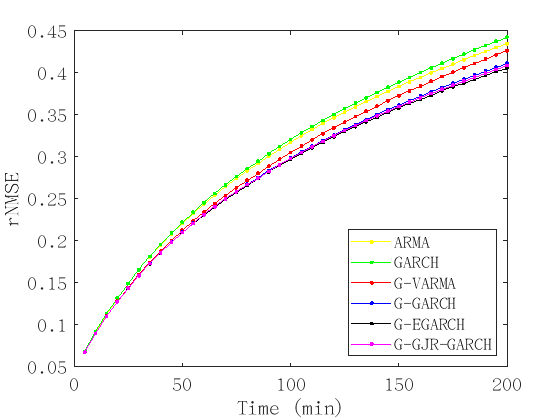

plot(t1,avg_rNMSE_H_ARMA(1:H,1),'.-y')
hold on;
plot(t1,avg_rNMSE_H_GARCH(1:H,1),'.-g')
hold on;
plot(t1,avg_rNMSE_H_GVARMA(1:H,1),'.-r')
hold on;
plot(t1,avg_rNMSE_H_G_GARCH(1:H,1),'.-b')
plot(t1,avg_rNMSE_H_G_EGARCH(1:H,1),'.-k')
hold on;
plot(t1,avg_rNMSE_H_G_GJR_GARCH(1:H,1),'.-m')
hold on;
xlabel('Time (min)'); ylabel('rNMSE')
legend({'ARMA','GARCH','G-VARMA','G-GARCH','G-EGARCH','G-GJR-GARCH'},'Location','southeast')
set(gca,'FontSize',15)

figure
t1 = 5:5:5*H

t1 =      5    10    15    20    25    30    35    40    45    50    55    60    65    70    75    80    85    90    95   100   105   110   115   120   125   130   135   140   145   150   155   160   165   170   175   180   185   190   195   200


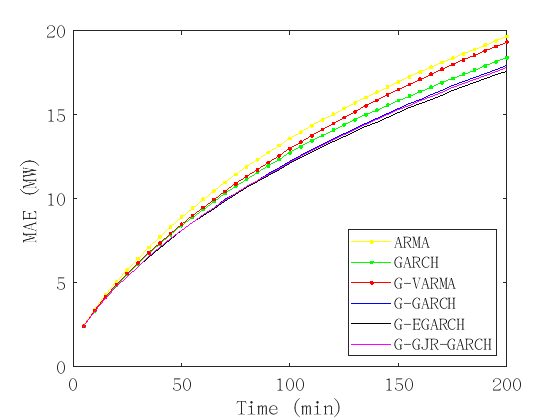

plot(t1,100*avg_MAE_H_ARMA,'.-y')
hold on;
plot(t1,100*avg_MAE_H_GARCH,'.-g')
plot(t1,100*avg_MAE_H_GVARMA,'.-r')
hold on;
plot(t1,100*avg_MAE_H_G_GARCH,'-b')
hold on;
plot(t1,100*avg_MAE_H_G_EGARCH,'-k')
hold on;
plot(t1,100*avg_MAE_H_G_GJR_GARCH,'-m')
hold on;
xlabel('Time (min)'); ylabel('MAE (MW)')
legend({'ARMA','GARCH','G-VARMA','G-GARCH','G-EGARCH','G-GJR-GARCH'},'Location','southeast')
set(gca,'FontSize',15)
ylim([0 20])

area = test_L

area = 4000

c_node = 1

c_node = 1

g = figure()

g =   Figure (14) - 属性:

      Number: 14
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [232 246 560 420]
       Units: 'pixels'

  显示 所有属性


t1 = 5:5:(5*area)

t1 =      5    10    15    20    25    30    35    40    45    50    55    60    65    70    75    80    85    90    95   100   105   110   115   120   125   130   135   140   145   150   155   160   165   170   175   180   185   190   195   200   205   210   215   220   225   230   235   240   245   250


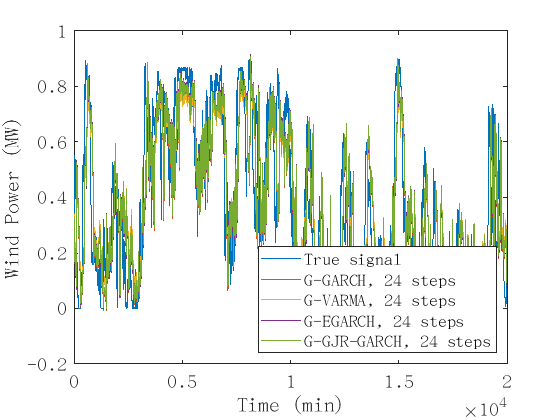

plot(t1,X_te(c_node,1:area))
hold on;
plot(t1,Pre_G_GARCH(c_node,1:area,24))
hold on;
plot(t1,Pre_GVARMA(c_node,1:area,24))
hold on;
plot(t1,Pre_G_EGARCH(c_node,1:area,24))
hold on;
plot(t1,Pre_G_GJR_GARCH(c_node,1:area,24))
xlabel('Time (min)'); ylabel('Wind Power (MW)')
legend({'True signal','G-GARCH, 24 steps','G-VARMA, 24 steps','G-EGARCH, 24 steps','G-GJR-GARCH, 24 steps'},'Location','southeast')
set(gca,'FontSize',15)

area = test_L

area = 4000

c_node = 6

c_node = 6

HH = 24

HH = 24

g = figure()

g =   Figure (28) - 属性:

      Number: 28
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [232 246 560 420]
       Units: 'pixels'

  显示 所有属性


t1 = 5:5:(5*area)

t1 =      5    10    15    20    25    30    35    40    45    50    55    60    65    70    75    80    85    90    95   100   105   110   115   120   125   130   135   140   145   150   155   160   165   170   175   180   185   190   195   200   205   210   215   220   225   230   235   240   245   250


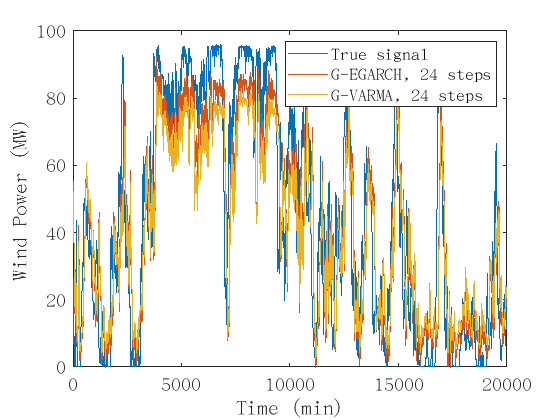

plot(t1,100*X_te(c_node,1:area))
hold on;
%plot(t1,100*Pre_G_GARCH(c_node,1:area,6))
plot(t1,100*Pre_G_EGARCH(c_node,1:area,HH))
plot(t1,100*Pre_GVARMA(c_node,1:area,HH))
%plot(t1,100*Pre_G_GJR_GARCH(c_node,1:area,6))
xlabel('Time (min)'); ylabel('Wind Power (MW)')
%legend({'True signal','G-GARCH, 6 steps','G-VARMA, 6 steps','G-EGARCH, 6 steps','G-GJR-GARCH, 6 steps'},'Location','northeast')
legend({'True signal','G-EGARCH, 24 steps','G-VARMA, 24 steps'},'Location','northeast')
set(gca,'FontSize',15)
ylim([0 100])
set(gca,'XtickLabel',{0,5000,10000,15000,20000})

node1 = 6

node1 = 6

h1 = 1

h1 = 1

E1 = max(error_G_EGARCH(node1,:,h1))

E1 = 0.2561

G1 = max(error_G_GARCH(node1,:,h1))

G1 = 0.2543

V1 = max(error_GVARMA(node1,:,h1))

V1 = 0.2516

GJR1 = max(error_G_GJR_GARCH(node1,:,h1))

GJR1 = 0.2540

G2  = max(error_GARCH(node1,:,h1))

G2 = 0.2596

A1 = max(error_ARMA(node1,:,h1))

A1 = 0.2566

%%%% DIFFERENCE ERROR 
error_dis = 100*(error_GVARMA - error_G_EGARCH)

error_dis = error_dis(:,:,1) =

  列 1 至 999

    0.0697    0.2864    0.6267   -0.5638   -0.7432   -0.3806    0.1823    0.3541   -0.5800    0.2095    0.2717   -0.4542    0.0015   -0.1720    0.2735    0.0097   -0.3680   -0.1053    0.0554    0.1234    0.0677    0.0358    0.0747    0.0831    0.0262    0.2845    0.2220    0.2903    0.5292    0.2109    0.2526    0.2998    0.2223   -0.3884   -0.4423    0.0904   -0.0096    0.1745    0.0171    0.0460    0.1673   -0.1140    0.1019    0.0964    0.0101    0.1962   -0.0224    0.1655   -0.0443    0.0418    0.0670    0.0687    0.0171    0.2456   -0.0527    0.1788    0.0912    0.1775   -0.1224   -0.1661   -0.0033   -0.0001    0.1364    0.0131   -0.0024    0.2126   -0.1732   -0.2696    0.1448   -0.2847    0.0755   -0.1557   -0.0544    0.1378    0.0239   -0.1177    0.3297    0.4837    0.7311    0.0123   -0.5891    0.3785   -0.3277   -0.0995    0.0418    0.0397    0.0829   -0.1274   -0.3005   -0.0466   -0.0301   -0.1133    0.0275    0.1773   -0.2033   -0

HH = 24

HH = 24

area = test_L

area = 4000

c_node = 6

c_node = 6

line_1 = zeros(1,test_L)

line_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


g = figure()

g =   Figure (32) - 属性:

      Number: 32
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [232 246 560 420]
       Units: 'pixels'

  显示 所有属性


t1 = 1:area

t1 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


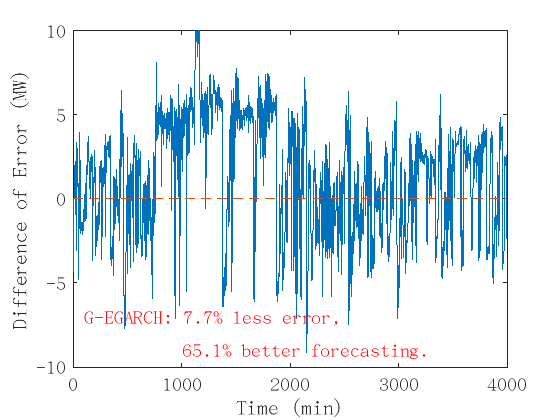

plot(t1,error_dis(c_node,1:area,HH))
hold on;
plot(t1,line_1(1,t1),'--')
xlabel('Time (min)'); ylabel('Difference of Error (MW)')
xlim([0 test_L])
ylim([-10 10])
text(100,-7,'G-EGARCH: 7.7% less error,','Color','red','FontSize',15)
text(1000,-9,'65.1% better forecasting.','Color','red','FontSize',15)
set(gca,'FontSize',15)




count = 0

count = 0

for i = 1:area
    if error_dis(c_node,i,HH) > 0
        count = count + 1;
    end
end

count/test_L

ans = 0.6508


error_1 = sum(error_GVARMA(c_node,1:area,HH));
error_2 = sum(error_G_GARCH(c_node,1:area,HH));
error_2/error_1

ans = 0.9229

area = test_L

area = 4000

c_node = 1

c_node = 1

g = figure()

g =   Figure (17) - 属性:

      Number: 17
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [232 246 560 420]
       Units: 'pixels'

  显示 所有属性


t1 = 5:5:(5*area)

t1 =      5    10    15    20    25    30    35    40    45    50    55    60    65    70    75    80    85    90    95   100   105   110   115   120   125   130   135   140   145   150   155   160   165   170   175   180   185   190   195   200   205   210   215   220   225   230   235   240   245   250


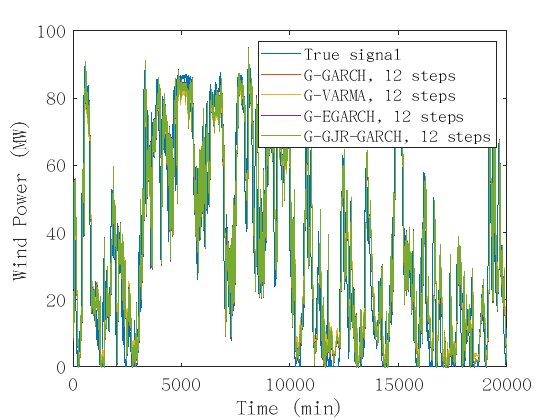

plot(t1,100*X_te(c_node,1:area))
hold on;
plot(t1,100*Pre_G_GARCH(c_node,1:area,12))
hold on;
plot(t1,100*Pre_GVARMA(c_node,1:area,12))
hold on;
plot(t1,100*Pre_G_EGARCH(c_node,1:area,12))
hold on;
plot(t1,100*Pre_G_GJR_GARCH(c_node,1:area,12))
xlabel('Time (min)'); ylabel('Wind Power (MW)')
legend({'True signal','G-GARCH, 12 steps','G-VARMA, 12 steps','G-EGARCH, 12 steps','G-GJR-GARCH, 12 steps'},'Location','northeast')
set(gca,'FontSize',15)
ylim([0 100])
set(gca,'XtickLabel',{0,5000,10000,15000,20000})

%%% 3 step ahead prediction
area = test_L

area = 4000

c_node = 6

c_node = 6

g = figure()

g =   Figure (19) - 属性:

      Number: 19
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [232 246 560 420]
       Units: 'pixels'

  显示 所有属性


t1 = 5:5:(5*area)

t1 =      5    10    15    20    25    30    35    40    45    50    55    60    65    70    75    80    85    90    95   100   105   110   115   120   125   130   135   140   145   150   155   160   165   170   175   180   185   190   195   200   205   210   215   220   225   230   235   240   245   250


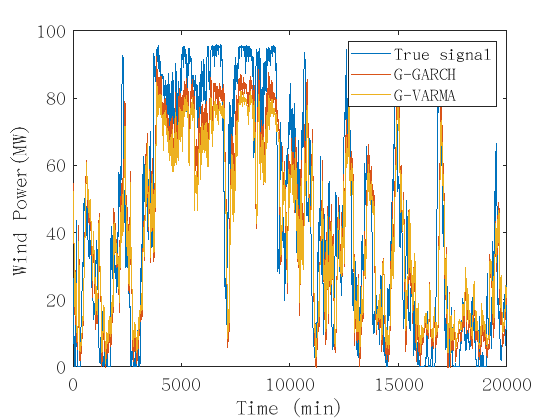

函数或变量 'Prediction_true' 无法识别。

函数或变量 'Prediction_true' 无法识别。

g =   Figure (23) - 属性:

      Number: 23
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [232 246 560 420]
       Units: 'pixels'

  显示 所有属性


t1 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


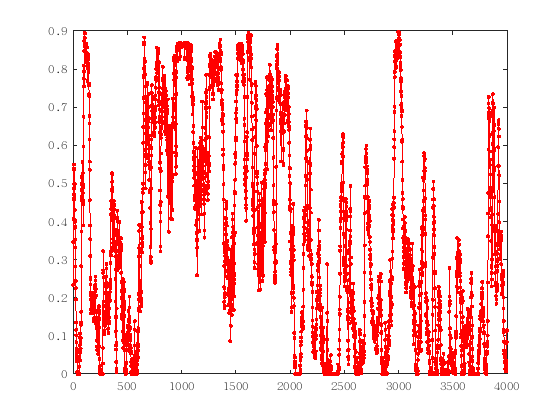

函数或变量 'Prediction_true' 无法识别。

plot(t1,100*X_te(c_node,1:area))
hold on;
plot(t1,100*Pre_G_GARCH(c_node,1:area,24))
hold on;
plot(t1,100*Pre_GVARMA(c_node,1:area,24))
xlabel('Time (min)'); ylabel('Wind Power(MW)')
legend({'True signal','G-GARCH','G-VARMA'},'Location','northeast')
set(gca,'FontSize',15)
ylim([0 100])
set(gca,'XtickLabel',{0,5000,10000,15000,20000})

% %%%%%%%   confidence interval
% [forData,YMSE] = forecast(EstMdl,step,'Y0',data);  
% lower = forData - 1.96*sqrt(YMSE); %95置信区间下限
% upper = forData + 1.96*sqrt(YMSE); %95置信区间上限

%%%% plot confidence interval of G-EGARCH
step = 24

step = 24

area = test_L

area = 4000

c_node = 6

c_node = 6

g = figure()

g =   Figure (20) - 属性:

      Number: 20
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [232 246 560 420]
       Units: 'pixels'

  显示 所有属性


t1 = 5:5:5*area

t1 =      5    10    15    20    25    30    35    40    45    50    55    60    65    70    75    80    85    90    95   100   105   110   115   120   125   130   135   140   145   150   155   160   165   170   175   180   185   190   195   200   205   210   215   220   225   230   235   240   245   250


t1conf = [t1 t1(end:-1:1)];
y_low = 100*Pre_G_EGARCH_low(c_node,1:area,step);
y_high = 100*Pre_G_EGARCH_high(c_node,1:area,step)

y_high =    97.0428   98.9155   94.0225   93.0140   89.2667   99.7338   96.7684   89.4982   83.8817   79.2089   72.3101   69.7998   66.8672   64.7135   66.3703   62.9277   59.7139   55.4949   53.2611   63.4222   76.8732   72.0926   71.5919   73.3977   71.6091   76.6258   77.7815   74.6952   67.4823   61.3100   62.2513   58.3474   61.5412   57.2769   52.3344   49.1341   46.0479   43.9781   47.9291   44.1969   42.2012   41.1427   38.1209   37.3174   38.6086   42.2793   43.7514   45.6035   50.9323   57.4820


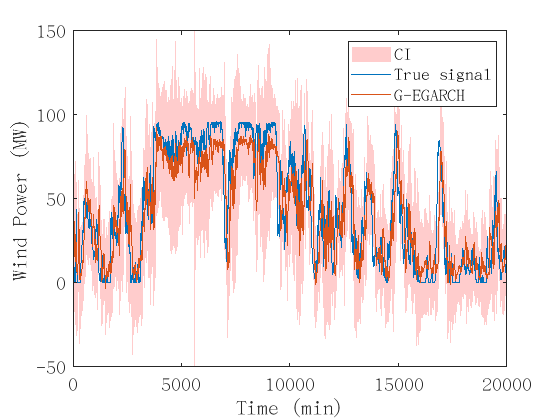

y_G_EGARCH_conf = [y_low y_high(end:-1:1)];
p_ggarch = fill(t1conf,y_G_EGARCH_conf,'red');
p_ggarch.FaceColor = [1 0.8 0.8];%定义区间的填充颜色      
p_ggarch.EdgeColor = 'none';%定义区间边界的填充颜色，此处不设置
hold on
plot(t1,100*X_te(c_node,1:area))
hold on;
plot(t1,100*Pre_G_EGARCH(c_node,1:area,step))
hold on;
xlabel('Time (min)'); ylabel('Wind Power (MW)')
legend({'CI','True signal','G-EGARCH'},'Location','northeast')
set(gca,'FontSize',15)
set(gca,'FontSize',15)
hold off
set(gca,'XtickLabel',{0,5000,10000,15000,20000})
ylim([-50 150])

%ylim([-10 50])

mean(Pre_G_EGARCH_low(c_node,1:area,step))

ans = 0.3240

%%%% plot confidence interval of G-EGARCH
step = 24

step = 24

area = test_L

area = 4000

c_node = 6

c_node = 6

g = figure()

g =   Figure (24) - 属性:

      Number: 24
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [232 246 560 420]
       Units: 'pixels'

  显示 所有属性


t1 = 5:5:5*area

t1 =      5    10    15    20    25    30    35    40    45    50    55    60    65    70    75    80    85    90    95   100   105   110   115   120   125   130   135   140   145   150   155   160   165   170   175   180   185   190   195   200   205   210   215   220   225   230   235   240   245   250


t1conf = [t1 t1(end:-1:1)];
y_low = 100*Pre_GARCH_low(c_node,1:area,step);
y_high = 100*Pre_GARCH_high(c_node,1:area,step)

y_high =   111.5992  104.5991   98.0882   98.4956   92.5663   92.4400   88.8237   85.9270   82.5787   78.0690   80.1540   80.3736   75.4713   69.9320   65.1087   60.2385   55.7979   51.7914   48.6535   49.4019   54.0205   50.4638   59.2970   55.3079   51.6230   48.7788   45.8560   42.9650   53.3430   48.6239   43.3605   38.5801   44.3725   40.4751   37.8037   34.2418   31.8063   29.9742   38.3376   34.7214   30.8409   30.7806   27.2785   25.3204   25.1109   40.1734   39.7963   43.0764   43.9419   62.3503


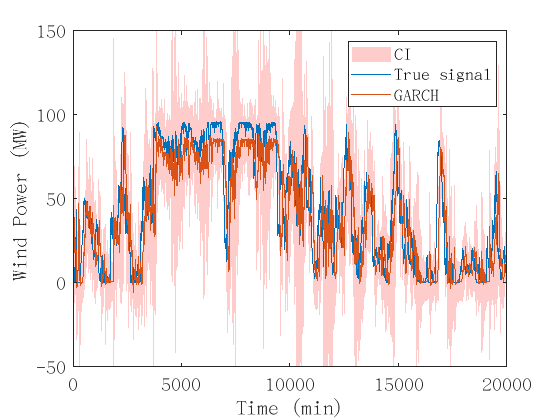

y_GARCH_conf = [y_low y_high(end:-1:1)];
p_ggarch = fill(t1conf,y_GARCH_conf,'red');
p_ggarch.FaceColor = [1 0.8 0.8];%定义区间的填充颜色      
p_ggarch.EdgeColor = 'none';%定义区间边界的填充颜色，此处不设置
hold on
plot(t1,100*X_te(c_node,1:area))
hold on;
plot(t1,100*Pre_GARCH(c_node,1:area,step))
hold on;
xlabel('Time (min)'); ylabel('Wind Power (MW)')
legend({'CI','True signal','GARCH'},'Location','northeast')
set(gca,'FontSize',15)
set(gca,'FontSize',15)
hold off
set(gca,'XtickLabel',{0,5000,10000,15000,20000})
%ylim([0 100])
ylim([-50 150])

step = 12

step = 12

line_arma_mae   = avg_MAE_H_ARMA(step,1)

line_arma_mae = 0.0998

line_arma_rnmse = avg_rNMSE_H_ARMA(step,1)

line_arma_rnmse = 0.2440

line_garch_mae   = avg_MAE_H_GARCH(step,1)

line_garch_mae = 0.0940

line_garch_rnmse = avg_rNMSE_H_GARCH(step,1)

line_garch_rnmse = 0.2456

line_gvarma_mae =  avg_MAE_H_GVARMA(step,1)

line_gvarma_mae = 0.0950

line_gvarma_rnmse =avg_rNMSE_H_GVARMA(step,1)

line_gvarma_rnmse = 0.2343


% principal component
Pre_G_GARCH_hpf = zeros(N,test_L,N);
diag_list = zeros(1,N)

diag_list =      0     0     0     0     0     0


error_GARCH_hpf = zeros(N,test_L,N);
MAE_H_GARCH_hpf = zeros(N,N);
avg_MAE_H_GARCH_hpf = zeros(N,1);
rNMSE_H_GARCH_hpf = zeros(N,N);
avg_rNMSE_H_GARCH_hpf = zeros(N,1);

Pre_G_EGARCH_hpf = zeros(N,test_L,N);
error_EGARCH_hpf = zeros(N,test_L,N);
MAE_H_EGARCH_hpf = zeros(N,N);
avg_MAE_H_EGARCH_hpf = zeros(N,1);
rNMSE_H_EGARCH_hpf = zeros(N,N);
avg_rNMSE_H_EGARCH_hpf = zeros(N,1);

for h_pass = 1:N
    diag_list(1,h_pass) = 1
    Pre_G_GARCH_hpf(:,:,h_pass) = V*diag(diag_list,0)*prediction(:,:,step);
    error_G_GARCH_hpf(:,:,h_pass) = abs(Pre_G_GARCH_hpf(:,:,h_pass) - X_te(:,:));
    MAE_H_G_GARCH_hpf(:,h_pass)  = sum(error_G_GARCH_hpf(:,:,h_pass),2)/(test_L);
    avg_MAE_H_G_GARCH_hpf(h_pass,1) = sum(MAE_H_G_GARCH_hpf(:,h_pass))/N;
    rNMSE_H_G_GARCH_hpf(:,h_pass) = sqrt(sum(error_G_GARCH_hpf(:,:,h_pass).^2,2)./sum(X_te(:,:).^2,2));
    avg_rNMSE_H_G_GARCH_hpf(h_pass,1) = sqrt(sum(sum(error_G_GARCH_hpf(:,:,h_pass).^2,2))/sum(sum(X_te(:,:).^2,2)));
    
    Pre_G_EGARCH_hpf(:,:,h_pass) = V*diag(diag_list,0)*prediction4(:,:,step);
    error_G_EGARCH_hpf(:,:,h_pass) = abs(Pre_G_EGARCH_hpf(:,:,h_pass) - X_te(:,:));
    MAE_H_G_EGARCH_hpf(:,h_pass)  = sum(error_G_EGARCH_hpf(:,:,h_pass),2)/(test_L);
    avg_MAE_H_G_EGARCH_hpf(h_pass,1) = sum(MAE_H_G_EGARCH_hpf(:,h_pass))/N;
    rNMSE_H_G_EGARCH_hpf(:,h_pass) = sqrt(sum(error_G_EGARCH_hpf(:,:,h_pass).^2,2)./sum(X_te(:,:).^2,2));
    avg_rNMSE_H_G_EGARCH_hpf(h_pass,1) = sqrt(sum(sum(error_G_EGARCH_hpf(:,:,h_pass).^2,2))/sum(sum(X_te(:,:).^2,2)));

end

diag_list =      1     0     0     0     0     0


diag_list =      1     1     0     0     0     0


diag_list =      1     1     1     0     0     0


diag_list =      1     1     1     1     0     0


diag_list =      1     1     1     1     1     0


diag_list =      1     1     1     1     1     1


%%%%%%%%%5
figure
hpf = 1:N

hpf =      1     2     3     4     5     6


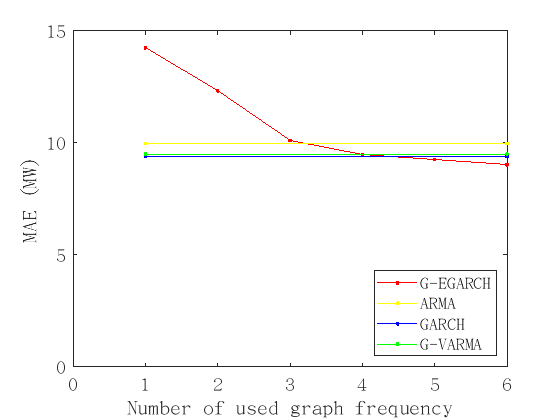

plot(hpf,100*avg_MAE_H_G_EGARCH_hpf(hpf,1),'.-r')
hold on;
plot([1,N],[100*line_arma_mae,100*line_arma_mae],'.-y')
plot([1,N],[100*line_garch_mae,100*line_garch_mae],'.-b')
plot([1,N],[100*line_gvarma_mae,100*line_gvarma_mae],'.-g')
%plot(hpf,avg_rNMSE_H_G_GARCH_hpf(h_pass,1),'.-g')
xlabel('Number of used graph frequency'); ylabel('MAE (MW)')
legend({'G-EGARCH','ARMA','GARCH','G-VARMA'},'Location','southeast')
set(gca,'FontSize',15)
ylim([0 15])
xlim([0 6])

%%%%%%%%%5
figure
hpf = 1:N

hpf =      1     2     3     4     5     6


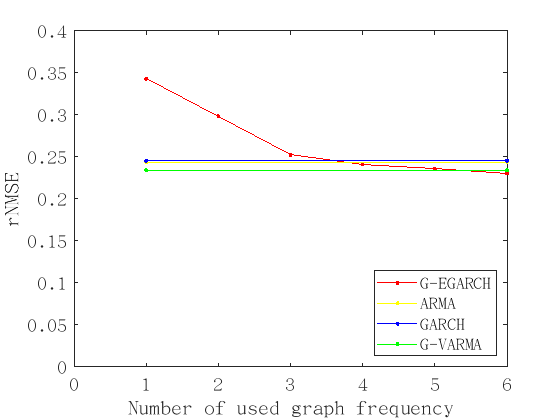

plot(hpf,avg_rNMSE_H_G_EGARCH_hpf(hpf,1),'.-r')
hold on;
plot([1,N],[line_arma_rnmse,line_arma_rnmse],'.-y')
plot([1,N],[line_garch_rnmse,line_garch_rnmse],'.-b')
plot([1,N],[line_gvarma_rnmse,line_gvarma_rnmse],'.-g')
xlabel('Number of used graph frequency'); ylabel('rNMSE')
legend({'G-EGARCH','ARMA','GARCH','G-VARMA'},'Location','southeast')
set(gca,'FontSize',15)
ylim([0 0.4])
xlim([0 6])